# **Multi-Class Instance Segmentation Training using Mask-RCNN **

Instance segmentation is computer vision technique which involves detection and localization of objects while simultaneously generating a segmentation map for each of the detected instances.

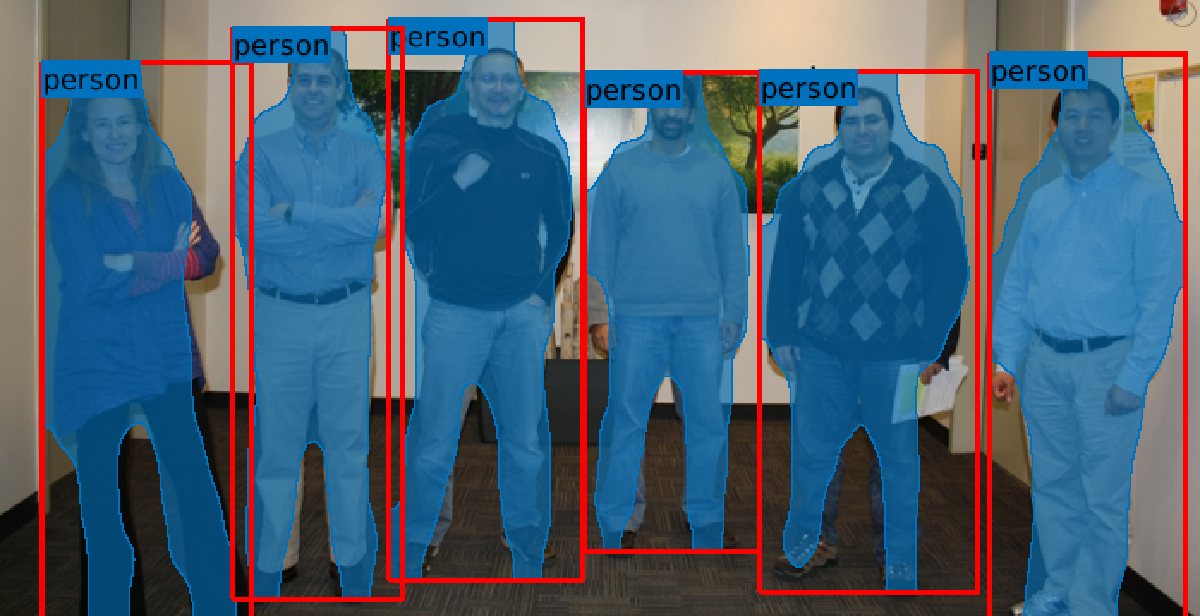

There are several deep learning algorithms for instance segmentation, the most popular being Mask-RCNN. The Mask-RCNN network belongs to RCNN family of networks and builds on the Faster-RCNN network to perform pixel level segmentation on the detected objects.

The Mask-RCNN network uses a Faster-RCNN network with - 

- A more accurate sub-pixel level ROI pooling layer - ROIAlign

- A Mask branch for pixel level object segmentation.

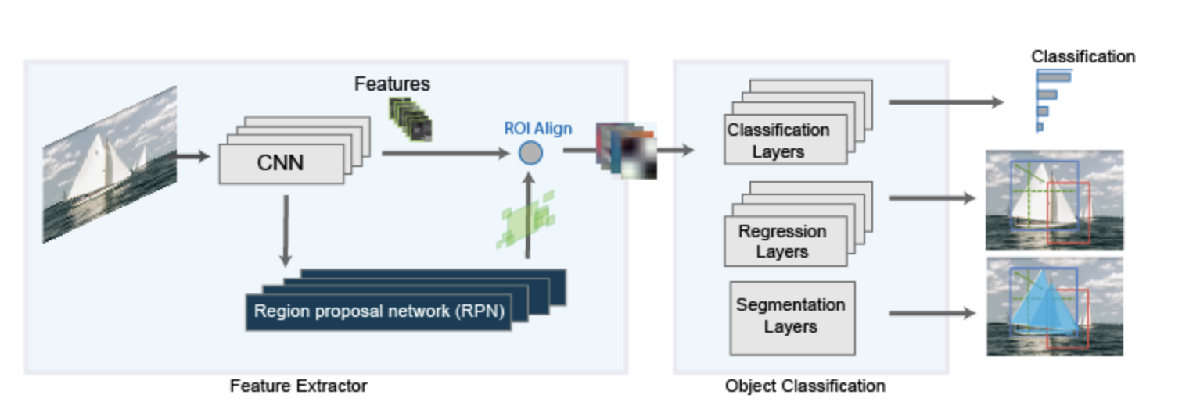

This network has two stages - 

- Stage 1: Region proposal network

- Stage 2: RCNN detector

Stage 1 predicts object proposal bounding boxes based on anchor boxes. while stage 2 refines these proposals, classifies them and computes the pixel level segmentation for these proposals.

## Prerequisites

To run this example you need the following prerequisites - 

- MATLAB (R2020b or later) with Computer Vision and Deep Learning Toolbox.

- Pretrained Mask-RCNN (download instructions below)

- COCO API's MATLAB API ([download link](https://github.com/cocodataset/cocoapi))

- COC0 2014 dataset with annotations ([download link](https://cocodataset.org/#download)) [For training only]

## Setup

- Add path to the repository's source directiory

% Add the source directory to the path
addpath('./src');

          2. Set the directory locations for the dataset and COCO API-

% Set the root directory for COCO API
cocoAPIDir = '/sandbox/adhar/maskRCNNFinal/cocoapi-master/cocoapi-master/MatlabAPI';
% Add the API directory to the path
addpath(cocoAPIDir);

         3. Set path's to the training images and annotation files

% Set directory locations for the coco dataset
trainImgFolder = '/local/coco/train2014';
annotationfile = '/local/coco/annotations/instances_train2014.json';

### **Download Pretrained Network**

Download a pretrained network to avoid having to wait for training to complete. If you want to train the network, set the `doTraining` variable to `true.`

doTraining = true;
if ~doTraining
    datadir = tempdir;
    url = 'https://www.mathworks.com/supportfiles/vision/data/maskrcnn_pretrained_person_car.mat';
    
    helper.downloadTrainedMaskRCNN(url, datadir);
    pretrained = load(fullfile(datadir, 'maskrcnn_pretrained_person_car.mat'));
    net = pretrained.net;
    
    % Extract Mask segmentation sub-network
    maskSubnet = helper.extractMaskNetwork(net);
end

## **Training Data**

The following example trains a mask-RCNN network to identify and segment the instances of persons and cars. To train a Mask-RCNN you need the followind data in the specified format-

**Input** 

- RGB images (H x W x 3)

**Ground-truth**

- Bounding boxes (NumObjects x 4,  arranged as [x y w h])

- Labels (NumObjects x 1), categorical

- Masks (H x W x NumObjects) 

### **Load and unpack training data **

The datastores managing the data must load them in the format described above.

The COCO annotations (bounding boxes, labels and masks) are unpacked to MAT files using COCO API for MATLAB, which can be downloaded from [here](https://cocodataset.org/#download). Each MAT file corresponds to a single training image and contains the following data -

- Train image file name

- bounding boxes

- labels

- masks

% Define teh categories to train the network on
trainCats = {'person','car'};

unpackAnnotationFolder = '/local/coco/annotations_unpacked/matFiles';

helper.unpackAnnotations(trainCats, annotationfile, trainImgFolder, unpackAnnotationFolder);

Loading and preparing annotations... DONE (t=41.06s).


### Create Datastore

Create datastore for dispatching input images and ground truth data. 

% Set image size for training
imageSize = [800 800 3];

% Create the training datastore to read image and ground truth data from
% the unpacked annotation MAT file
ds = fileDatastore(unpackAnnotationFolder, 'ReadFcn',@(x)helper.cocoAnnotationMATReader(x, trainImgFolder));

To prepare data for training, resize the images and ground truth data to the size expected by the network.

trainDS = transform(ds, @(x)helper.preprocessData(x, imageSize));

Lets preview the data returned by combine datastore-

trainDS.shuffle();
data = preview(trainDS)

data = 1×4 cell array
    {800×800×3 uint8}    {12×4 double}    {12×1 categorical}    {800×800×12 logical}


For a custom datastore compatible with training code in this example, ensure the datastore returns a 1x4 cell , containing the image, bounding boxes, categorical labels and mask stacks, in order. The format for each of this data is specified above.

## **Network**

### **Network creation**

The Mask-RCNN network builds upon the Faster-RCNN network. So, for network creation we will add to the faster-RCNNlayers created using **fasterRCNNLayers** function.

classNames = trainCats;
numClasses = numel(classNames);
% Add a background class
classNames = [classNames {'background'}];

Other network configuration parameters are defined in the createNetworkConfiguration funtions. Any customization of the input prameters can me made inside this function.

params = createMaskRCNNConfig(imageSize, numClasses, classNames);
disp(params);

                               ImageSize: [800 800 3]
                              NumClasses: 2
                              ClassNames: {'person'  'car'  'background'}
                         BackgroundClass: 'background'
                      ROIAlignOutputSize: [14 14]
                          MaskOutputSize: [14 14]
                             ScaleFactor: [0.0625 0.0625]
                      ClassAgnosticMasks: 1
                    PositiveOverlapRange: [0.6000 1]
                    NegativeOverlapRange: [0.1000 0.6000]
                             AnchorBoxes: [15×2 double]
                              NumAnchors: 15
                      NumRegionsToSample: 200
                        OverlapThreshold: 0.7000
                                MinScore: 0
    NumStrongestRegionsBeforeProposalNMS: 3000
                     NumStrongestRegions: 1000
                            BoxFilterFcn: @(a,b,c,d)fasterRCNNObjectDetector.filterBBoxesBySize(a,b,c,d)
                     

For the creation of the network, we start with Faster-RCNN layers and,

- Replace roiMaxPooling2dLayer with **roiAlignLayer** .

- Add a mask segmentation head for pixel level segmentation.

% Create the maskRCNN network
dlnet = createMaskRCNN(numClasses, params);

## Train Network

Train on a GPU, if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher.The following code automatically detects if you have a GPU available and sets the `executionEnvironment` setting to either "gpu" or "cpu".

if canUseGPU
    executionEnvironment = "gpu";
else
    executionEnvironment = "cpu";
end

### **Training Options**

The training options used here are similar to those specified in the Mask-RCNN paper.

% SGDM learning parameters
initialLearnRate = 0.01;
momemtum = 0.9;
decay = 0.0001;
velocity = [];
maxEpochs = 30;

minibatchSize = 2;

### Training

The next step is configure the dispatch of training data. We use minibatchqueue to configure the training data as dlarray with a specified data format, configured the device described by executionEnvironment.

% Configure the data dispatcher

% Create the batching function. The images are concatenated along the 4th
% dimension to get a HxWxCxminiBatchSize shaped batch. The other ground truth data is
% configured a cell array of length = minibatchSize.

myMiniBatchFcn = @(img, boxes, labels, masks) deal(cat(4, img{:}), boxes, labels, masks);

mb = minibatchqueue(trainDS, 4, "MiniBatchFormat", ["SSCB", "", "", ""],...
                            "MiniBatchSize", minibatchSize,...
                            "OutputCast", ["single","","",""],...
                            "OutputAsDlArray", [true, false, false, false],...
                            "MiniBatchFcn", myMiniBatchFcn,...
                            "OutputEnvironment", [executionEnvironment,"cpu","cpu","cpu"]);

Finally, specify the custom training loop. For each iteration:

- Read from the minibatchqueue.

- Evaluate the model gradients using `dlfeval` and the `modelGradients` function. The function `modelGradients`, listed as a supporting function, returns the gradients of the loss with respect to the learnable parameters in `net`, the corresponding mini-batch loss, and the state of the current batch.

- Update the network parameters using the `sgdmupdate` function.

- Update the `state` parameters of `net` with the moving average.

- Update the training progress plot.

 
Training on GPU.
|=========================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |      Rate       |
|=========================================================================|


|    1    |      1      |    00:00:09    |    3.0171    |     0.0100      | 


|    1    |      2      |    00:00:16    |    1.6990    |     0.0100      | 


|    1    |      3      |    00:00:24    |    2.0708    |     0.0100      | 


|    1    |      4      |    00:00:32    |    1.5980    |     0.0100      | 


|    1    |      5      |    00:00:40    |    6.6779    |     0.0100      | 


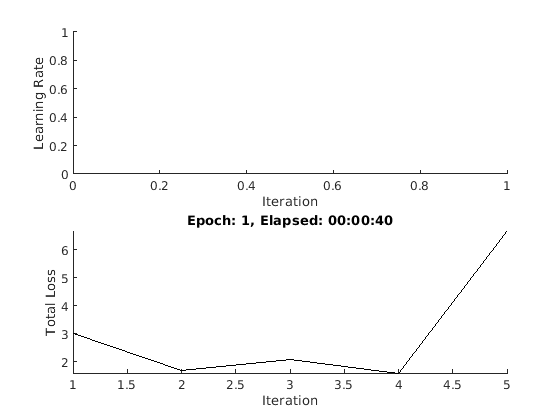

numEpoch = 1;
numIteration = 1; 

start = tic;
if doTraining
    
     % Create subplots for the learning rate and mini-batch loss.
    fig = figure;
    [lossPlotter] = helper.configureTrainingProgressPlotter(fig);
    
    % Initialize verbose output
    helper.initializeVerboseOutput([]);
    
    % Custom training loop.
    while numEpoch < maxEpochs
    mb.reset();
    mb.shuffle();
    
        while mb.hasdata()
            % get next batch from minibatchqueue
            [X, gtBox, gtClass, gtMask] = mb.next();
        
            % Evaluate the model gradients and loss using dlfeval
            [gradients, loss, state] = dlfeval(@networkGradients, X, gtBox, gtClass, gtMask, dlnet, params);
            dlnet.State = state;
            
            % compute the learning rate for current iteration
            learnRate = initialLearnRate/(1 + decay*numIteration);
            
            if(~isempty(gradients) && ~isempty(loss))
    
                [dlnet.Learnables, velocity] = sgdmupdate(dlnet.Learnables, gradients, velocity, learnRate, momemtum);
            else
                continue;
            end
            helper.displayVerboseOutputEveryEpoch(start,learnRate,numEpoch,numIteration,loss);
                
            % Plot loss/ accuracy metric
             D = duration(0,0,toc(start),'Format','hh:mm:ss');
            addpoints(lossPlotter,numIteration,double(gather(extractdata(loss))))
            
            subplot(2,1,2)

            title("Epoch: " + numEpoch + ", Elapsed: " + string(D))
           
            drawnow
            
            numIteration = numIteration + 1;
    
        end
    numEpoch = numEpoch + 1;
    
    end
end

net = dlnet;

## **Detect Objects using Mask-RCNN**

Inference is performed on the trained MaskRCNN using the detectMaskRCNN function. 

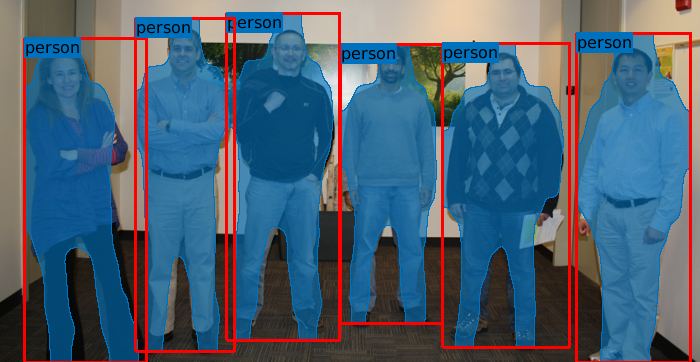

% Read the image for inference
img = imread('visionteam.jpg');

% Define the target size of the image for inference
targetSize = [700 700 3];

% Resize the image maintaining the aspect ratio and scaling the largest
% dimension to the target size.
imgSize = size(img);
[~, maxDim] = max(imgSize);
resizeSize = [NaN NaN]; 
resizeSize(maxDim) = targetSize(maxDim);

img = imresize(img, resizeSize);

% detect the objects and their masks
[boxes, scores, labels, masks] = detectMaskRCNN(net, maskSubnet, img, params, executionEnvironment);

% Visualize Predictions

% Overlay the detected masks on the image using the insertObjectMask
% function.
if(isempty(masks))
    overlayedImage = img;
else
    overlayedImage = insertObjectMask(img, masks);
end
figure, imshow(overlayedImage)

% Show the bounding boxes and labels on the objects
showShape("rectangle", gather(boxes), "Label", labels, "LineColor",'r')

*Copyright 2020 The MathWorks, Inc.*